clear;
close all;
clc;
clf;
% constants for the sun
duS = 1.4959965e8; % conversion from du sun to km
au = duS; % a sun du is sometimes called an au
tuS = 5.0226757e6; % converson from tu sun to seconds
muS = 1.3271544e11; % mu for sun km^3/s^2
vuS = duS/tuS;
% constants for earth
duE = 6378.136; % conversion from du earth to km
tuE = 806.8118744; % converson from tu earth to seconds
muE = 3.986004418e5; % mu for earth

% constants for jupiter
muJ = 1.268e8;
duJ = 71370;

% magnitude of a vector
mag = @(vector) (dot(vector,vector))^0.5;

%position at j2000 T = January 1, 2000 at 11:58 am UTC
Tj2000 = datetime('2000-01-01 23:58:00');

%Mercury
elementsMercury.a        = 0.387099;
elementsMercury.e        = 0.205631;
elementsMercury.i        = (7.00487);
elementsMercury.bigOmega = (48.33167);
elementsMercury.omega    = (29.12478);
elementsMercury.nu       = (174.7944);
[rMej2000,vMej2000] = elements2rv(elementsMercury,1);

%Venus
elementsVenus.a        = 0.723332;
elementsVenus.e        = 0.006773;
elementsVenus.i        = (3.39471);
elementsVenus.bigOmega = (76.68069);
elementsVenus.omega    = (54.85229);
elementsVenus.nu       = (50.44675);
[rVj2000,vVj2000] = elements2rv(elementsVenus,1);

%Earth
elementsEarth.a        = 1.000000;
elementsEarth.e        = 0.01671;
elementsEarth.i        = (0.00005);
elementsEarth.bigOmega = (-11.26064);
elementsEarth.omega    = (114.20783);
elementsEarth.nu       = (-2.48284);
[rEj2000,vEj2000] = elements2rv(elementsEarth,1);

%Mars
elementsMars.a        = 1.523662;
elementsMars.e        = 0.093412;
elementsMars.i        = (1.85061);
elementsMars.bigOmega = (49.57854);
elementsMars.omega    = (286.4623);
elementsMars.nu       = (19.41248);
[rMaj2000,vMaj2000] = elements2rv(elementsMars,1);

%Jupiter
elementsJupiter.a        = 5.203363;
elementsJupiter.e        = 0.048393;
elementsJupiter.i        = (1.3053);
elementsJupiter.bigOmega = (100.55615);
elementsJupiter.omega    = (-85.8023);
elementsJupiter.nu       = (19.55053);
[rJj2000,vJj2000] = elements2rv(elementsJupiter,1);

%Saturn
elementsSaturn.a        = 9.537070;
elementsSaturn.e        = 0.054151;
elementsSaturn.i        = (2.48446);
elementsSaturn.bigOmega = (113.71504);
elementsSaturn.omega    = (-21.2831);
elementsSaturn.nu       = (-42.4876);
[rSj2000,vSj2000] = elements2rv(elementsSaturn,1);

%Uranus
elementsUranus.a        = 19.19126;
elementsUranus.e        = 0.047168;
elementsUranus.i        = (0.76986);
elementsUranus.bigOmega = (74.22988);
elementsUranus.omega    = (96.73436);
elementsUranus.nu       = (142.2679);
[rUj2000,vUj2000] = elements2rv(elementsUranus,1);

%Neptune 
elementsNeptune.a        = 30.06896;
elementsNeptune.e        = 0.008586;
elementsNeptune.i        = (1.76917);
elementsNeptune.bigOmega = (131.72169);
elementsNeptune.omega    = (-86.75034);
elementsNeptune.nu       = (259.9087);
[rNj2000,vNj2000] = elements2rv(elementsNeptune,1);

%Pluto 
elementsPluto.a        = 39.48169;
elementsPluto.e        = 0.248808;
elementsPluto.i        = (17.14175);
elementsPluto.bigOmega = (110.30347);
elementsPluto.omega    = (113.76329);
elementsPluto.nu       = (14.86205);
[rPj2000,vPj2000] = elements2rv(elementsPluto,1);


% project task 1:
% start date
Tstart = datetime('2025-Dec-25 8:37:00');

% time elapsed between epoch start and start date
DT = seconds(Tstart - Tj2000)/tuS;

%Mercury
[rMestart,vMestart] = timeOfFlight(rMej2000,vMej2000,DT);
elementsMercuryStart = rv2elements(rMestart,vMestart,1);

%Venus
[rVstart,vVstart] = timeOfFlight(rVj2000,vVj2000,DT);
elementsVenusStart = rv2elements(rVstart,vVstart,1);

%Earth
[rEstart,vEstart] = timeOfFlight(rEj2000,vEj2000,DT);
elementsEarthStart = rv2elements(rEstart,vEstart,1);

%Mars
[rMastart,vMastart] = timeOfFlight(rMaj2000,vMaj2000,DT);
elementsMarsStart = rv2elements(rMastart,vMastart,1);

%Jupiter
[rJstart,vJstart] = timeOfFlight(rJj2000,vJj2000,DT);
elementsJupiterStart = rv2elements(rJstart,vJstart,1);

%Saturn
[rSstart,vSstart] = timeOfFlight(rSj2000,vSj2000,DT);
elementsSaturnStart = rv2elements(rSstart,vSstart,1);

%Uranus
[rUstart,vUstart] = timeOfFlight(rUj2000,vUj2000,DT);
elementsUranusStart = rv2elements(rUstart,vUstart,1);

%Neptune 
[rNstart,vNstart] = timeOfFlight(rNj2000,vNj2000,DT);
elementsNeptuneStart = rv2elements(rNstart,vNstart,1);

%Pluto 
[rPstart,vPstart] = timeOfFlight(rPj2000,vPj2000,DT);
elementsPlutoStart = rv2elements(rPstart,vPstart,1);

% task 2

% earth to jupiter:
% time of flight 35 days
tof3 = 10.1;
tofsec3 = tof3*tuS

tofsec3 = 5.0729e+07

% arrival day is 
Tarrival = datetime('2034-Dec-30 15:21:00');
TdepartEarthForJupiter = Tarrival - seconds(tof3*tuS);
% position is
DT = seconds(Tarrival - Tj2000)/tuS;

% position of jupiter at arrival
[rJa,vJa] = timeOfFlight(rJj2000,vJj2000,DT)

rJa =     4.8079
    1.1789
   -0.1126


vJa =    -0.1099
    0.4468
    0.0006


[rEAa,vEAa] = timeOfFlight(rEj2000,vEj2000,DT)

rEAa =    -0.1366
    0.9738
    0.0000


vEAa =    -1.0067
   -0.1427
   -0.0000


% position of earth at departure for jupiter
[rdE2,vdE2] = timeOfFlight(rEj2000,vEj2000,(DT-tof3));
[rFBJ2,vFBJ2] = timeOfFlight(rJj2000,vJj2000,(DT-tof3));
elementsJa = rv2elements(rJa,vJa,1);
elementsdE2 = rv2elements(rdE2,vdE2,1);
%displayOrbit(elementsdE2,elementsJa)

% vleocitys of the transfer orbit at jupiter and earth
[velocityAfterGravityAssist,velocityAtJupiterSOIArrival,~,~] = gaussSolution(rdE2,rJa,tof3);


elementsAfterGA = rv2elements(rdE2,velocityAfterGravityAssist,1);



% find velocity need to exit hyperbolic orbit arround earth:
velocityHyperInfinityEarthDeparture = velocityAfterGravityAssist - vdE2;


% ecentricity of the hyperbolic orbit arround earth for the gravity assist
e = 1.9;

% turn angle delta
delta = 2*asin(1/e);

% to gravity assist matrix
GA = [cos(delta) -sin(delta) 0;
      sin(delta) cos(delta)  0;
      0          0           1;];

% calculating the arrival velocity from the gravity assist
velocityHyperInfinityEarthArrival  = GA^-1*velocityHyperInfinityEarthDeparture;

% velocity that it is nessesary to arrive at earth with to do the gravity
% assist to jupiter
velocityEarthArrivalFromSpace = velocityHyperInfinityEarthArrival + vdE2;
% orbital elements of that orbit
elementsSpacePart2 = rv2elements(rdE2,velocityEarthArrivalFromSpace,1)

elementsSpacePart2 = struct with fields:
           a: 1.0318
           e: 0.3656
           i: 2.4466
    bigOmega: 60.7568
       omega: 71.3450
          nu: 108.6561
           u: 180.0011


% plot of 1/2 of the orbit

%[x1,y1,z1] = orbitPoints(elementsSpacePart2,[-60 108]);
%plot3(x1,y1,z1,'m')
elementsSpacePart2.nu = 300;
[rSpacePoint,vSpacePoint2] = elements2rv(elementsSpacePart2,1)

rSpacePoint =     0.2324
    0.7191
    0.0063


vSpacePoint2 =    -1.2925
    0.0652
    0.0496


timeFromSpaceToEarth = timeBetween(elementsSpacePart2,360,300,1)+timeBetween(elementsSpacePart2,0,108,1)

timeFromSpaceToEarth = 1.7216

timeFromSpaceToEarth*tuS

ans = 8.6469e+06

timeAtSpacePoint = TdepartEarthForJupiter-timeFromSpaceToEarth;
timeToSpacePoint = 2;
time2sec = timeToSpacePoint*tuS

time2sec = 1.0045e+07

timeAtEarthDeparture500Orbit = timeAtSpacePoint-timeToSpacePoint

timeAtEarthDeparture500Orbit = datetime
   18-May-2033 18:38:10


timeBetweenEarthDepartureAndj2000 = seconds(timeAtEarthDeparture500Orbit-Tj2000)/tuS;
% earth position at the spacecraft departure
[rEarthDepart,velocityEarthDepart] = timeOfFlight(rEj2000,vEj2000,timeBetweenEarthDepartureAndj2000);
[rJDepart,velocityJDepart] = timeOfFlight(rJj2000,vJj2000,timeBetweenEarthDepartureAndj2000);

% finds the velocity that it is nessesary to depart earth with and
% the arrival velocity at the space point.
[~,~,velocityDepartEarth,velocitySpaceArrival] = gaussSolution(rEarthDepart,rSpacePoint,timeToSpacePoint);
elementsDepartOrbit1 = rv2elements(rEarthDepart,velocityDepartEarth,1)

elementsDepartOrbit1 = struct with fields:
           a: 0.9285
           e: 0.3213
           i: 1.8685
    bigOmega: 57.1747
       omega: 303.4003
          nu: 236.6011
           u: 180.0014


velocityInfinityDepart = velocityDepartEarth - velocityEarthDepart;
% vinf^2 + 2mu/rph = vph^2

velocityDepartEarthHyperbolicPeriapsis = sqrt(dot(velocityInfinityDepart,velocityInfinityDepart)*vuS + 2*muE/(duE+500));
velocity500CircularOrbit = sqrt(muE/(duE+500));
deltaV1 = velocityDepartEarthHyperbolicPeriapsis-velocity500CircularOrbit %km/s

deltaV1 = 3.2934

deltaV2 = mag(velocitySpaceArrival-vSpacePoint2)*vuS %km/s

deltaV2 = 19.9678

velocityhyperInfinityJupeterArrival = velocityAtJupiterSOIArrival-vJa;
velocityHyperJupiterPeriapsis = sqrt(dot(velocityhyperInfinityJupeterArrival,velocityhyperInfinityJupeterArrival)*vuS + 2*muJ/(duJ+10000));
velocityJupiterCircle = sqrt(muJ/(duJ+10000));
deltaV3 = velocityHyperJupiterPeriapsis-velocityJupiterCircle

deltaV3 = 16.3753

totalDeltaV = deltaV3+deltaV2+deltaV1

totalDeltaV = 39.6365

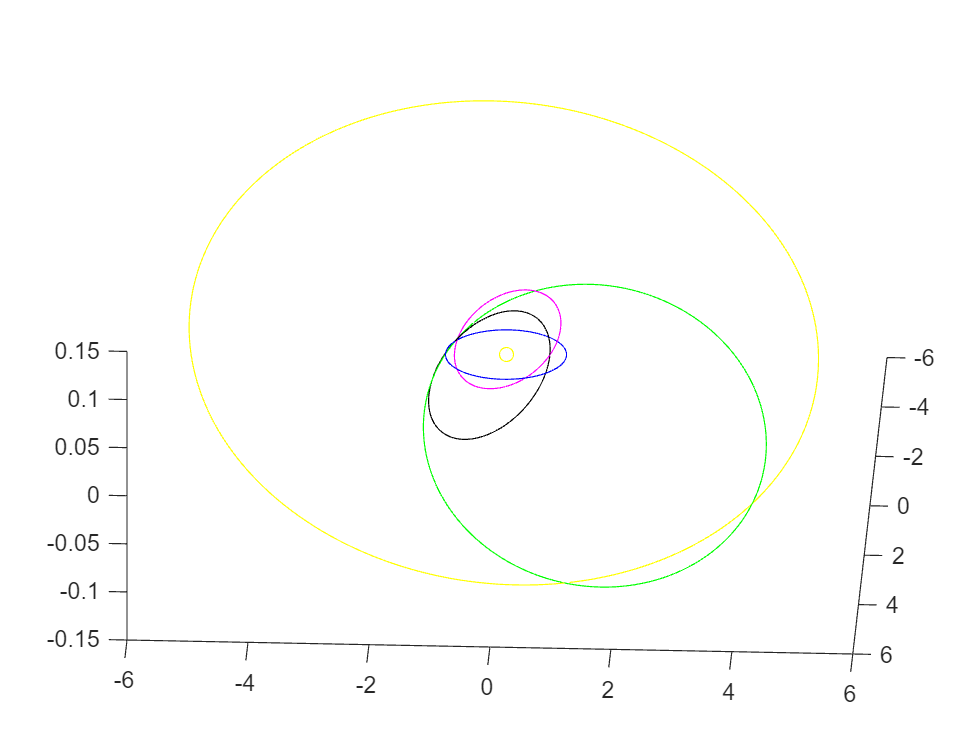

displayOrbit(elementsdE2,elementsAfterGA,elementsJa,elementsDepartOrbit1,elementsSpacePart2)

function [time] = timeBetween(element,nu1,nu2,mu)
%This function finds the time between two true anomalys given the orbital
%elements

E = @(e,nu) acos((e+cosd(nu))/(1+e*cosd(nu)));

n = @(mu,a) sqrt(mu/(a^3));

M = @(E,e) E - e*sin(E);

E1 = E(element.e,nu1);
E2 = E(element.e,nu2);

meanMotion = n(mu,element.a);

M1 = M(E1,element.e);
M2 = M(E2,element.e);
time = (M2-M1)/meanMotion;

end

function [r1,v1] = timeOfFlight(r0,v0,tof)
% this function finds some new r and v vectors from an initial vector and a
% time of flight everything must be in canonical units

    xguess = 1000;

    mag = @(vector) sqrt(vector(1)^2 + vector(2)^2 + vector(3)^2); % magnitude of a 3 element vector

    elements = rv2elements(r0,v0,1);



    error = 1;
    x = xguess;

    while error > 1*10^(-5)

        znplus1 = x^2/elements.a;

        [s,c] = fofZ(znplus1);

        t = x^3*s + dot(r0,v0)*x^2*c+mag(r0)*x*(1-znplus1*s);

        rn = x^2*c+dot(r0,v0)*x*(1-znplus1*s)+mag(r0)*(1-znplus1*c);

        error = abs(tof - t);

        dtdx = rn;

        x = x + (tof-t)/dtdx;
        

    end

    f = 1 - elements.a/mag(r0)*(1 - cos(x/sqrt(elements.a)));

    fdot = -sqrt(elements.a)/(mag(r0)*rn)*sin(x/sqrt(elements.a));

    g = (elements.a)^2/sqrt(elements.a)*(dot(r0,v0)/sqrt(elements.a)*(1-cos(x/sqrt(elements.a)))+mag(r0)/elements.a*sin(x/sqrt(elements.a)));
    
    gdot = 1 - elements.a/rn + elements.a/rn*cos(x/sqrt(elements.a));

    check = f*gdot-fdot*g;

    r1 = f*r0 + g*v0;
    v1 = fdot*r0 + gdot*v0;

    

    function [s,c] = fofZ(z) % this function finds the s and c values for a given z

    if z > 0.1
        s = (sqrt(z)-sin(sqrt(z)))/z^(3/2);
        c = (1-cos(sqrt(z)))/z;
    elseif z < -0.1
        s = (sinh(-z)-sqrt(-z))/(-z)^(3/2);
        c = (1 - cosh(-z))/z;
    else
        s = 1/6 - z/factorial(5) + z^2/factorial(7) - z^3/factorial(9);
        c = 1/2 - z/factorial(4) + z^2/factorial(6) - z^3/factorial(8);

    end
    end

end

function [V1s,V2s,V1l,V2l] = gaussSolution(r1,r2,tof)
    % this function finds the solution to gausses problem when given values
    % for position in DU and a TOF in TU. The s are the short way and
    % the l is the long way.

    zguess = 10;

    mag = @(vector) sqrt(dot(vector,vector)); % magnitude of a vector

    dtheta = acos(dot(r1,r2)/(mag(r1)*mag(r2))); % the angle between the position vectors

    A = (sqrt(mag(r1)*mag(r2))*sin(dtheta))/sqrt(1-cos(dtheta)); 


    error = 1;
    znplus1 = zguess;

    while error > 1*10^(-5)
        [s,c] = fofZ(znplus1);

        y = mag(r1) + mag(r2) - A*(1-znplus1*s)/sqrt(c);

       x = sqrt(y/c);

       t = x^3*s + A*sqrt(y);

       error = abs(tof - t);
     

        dsdz = (c - 3*s)/2*znplus1;

        dcdz = (1 - znplus1*s - 2*c)/2*znplus1;

       dtdz = x^3 * (dsdz - 3*s*dcdz/(2*c)) + A/8 * (3*s*sqrt(y)/c + A/x);

      znplus1 = znplus1 + (tof-t)/dtdz;

    end

    f = 1 - y/mag(r1);
    fdot = -x/(mag(r1)*mag(r2))*(1-znplus1*s);
    g = A*sqrt(y);
    gdot = 1 - y/mag(r2);

    V1s = (r2 - f*r1)/g;
    V2s = (gdot*r2 - r1)/g;


    check = f*gdot-fdot*g;

    dthetal = 2*pi-dtheta; % the angle between the position vectors

    Al = (sqrt(mag(r1)*mag(r2))*sin(dthetal))/sqrt(1-cos(dthetal)); 


    error = 1;
    znplus1 = zguess;

    while error > 1*10^(-5)
        [s,c] = fofZ(znplus1);

        y = mag(r1) + mag(r2) - Al*(1-znplus1*s)/sqrt(c);

       x = sqrt(y/c);

       t = x^3*s + Al*sqrt(y);

       error = abs(tof - t);

        dsdz = (c - 3*s)/2*znplus1;

        dcdz = (1 - znplus1*s - 2*c)/2*znplus1;

       dtdz = x^3 * (dsdz - 3*s*dcdz/(2*c)) + Al/8 * (3*s*sqrt(y)/c + Al/x);

      znplus1 = znplus1 + (tof-t)/dtdz;

    end

    f = 1 - y/mag(r1);
    fdot = -x/(mag(r1)*mag(r2))*(1-znplus1*s);
    g = Al*sqrt(y);
    gdot = 1 - y/mag(r2);

    V1l = (r2 - f*r1)/g;
    V2l = (gdot*r2 - r1)/g;


    check = f*gdot - fdot*g;

    function [s,c] = fofZ(z) % this function finds the s and c values for a given z

    if z > 0.1
        s = (sqrt(z)-sin(sqrt(z)))/z^(3/2);
        c = (1-cos(sqrt(z)))/z;
    elseif z < -0.1
        s = (sinh(-z)-sqrt(-z))/(-z)^(3/2);
        c = (1 - cosh(-z))/z;
    else
        s = 1/6 - z/factorial(5) + z^2/factorial(7) - z^3/factorial(9);
        c = 1/2 - z/factorial(4) + z^2/factorial(6) - z^3/factorial(8);

    end
    end

end

function [] = displayOrbit(elements1,elements2,elements3,elements4,elements5)
%given a set of orbital elements this function plots the orbit
%   pass in two sets of orbital elements

% orbital points initilize
x1 = zeros(100,1);
y1 = zeros(100,1);
z1 = zeros(100,1);

x2 = zeros(100,1);
y2 = zeros(100,1);
z2 = zeros(100,1);

x3 = zeros(100,1);
y3 = zeros(100,1);
z3 = zeros(100,1);

x4 = zeros(100,1);
y4 = zeros(100,1);
z4 = zeros(100,1);

x5 = zeros(100,1);
y5 = zeros(100,1);
z5 = zeros(100,1);

for i = 1:1:360
    elements1.nu = (i-1);
    [rtemp,~] = elements2rv(elements1,1);
    x1(i) = rtemp(1);
    y1(i) = rtemp(2);
    z1(i) = rtemp(3);

    elements2.nu = (i-1);
    [rtemp,~] = elements2rv(elements2,1);
    x2(i) = rtemp(1);
    y2(i) = rtemp(2);
    z2(i) = rtemp(3);

    elements3.nu = (i-1);
    [rtemp,~] = elements2rv(elements3,1);
    x3(i) = rtemp(1);
    y3(i) = rtemp(2);
    z3(i) = rtemp(3);

    elements4.nu = (i-1);
    [rtemp,~] = elements2rv(elements4,1);
    x4(i) = rtemp(1);
    y4(i) = rtemp(2);
    z4(i) = rtemp(3);

    elements5.nu = (i-1);
    [rtemp,~] = elements2rv(elements5,1);
    x5(i) = rtemp(1);
    y5(i) = rtemp(2);
    z5(i) = rtemp(3);
end

plot3(x1,y1,z1,'b')
hold on;
plot3(x2,y2,z2,'g')
plot3(x3,y3,z3,'y')
plot3(x4,y4,z4,'m')
plot3(x5,y5,z5,'k')
plot3(0,0,0,'yo')


end

function [rijk,vijk] = elements2rv(elements,mu)
%elements2rv this function converts a set of orbital elements to r and v
%   it takes orbital elements ad returns the r and v vectors in the ijk
%   coordinate system

p = (1-(elements.e)^2)*elements.a;

rpqwMag = p/(1+elements.e*cosd(elements.nu));

rpqw(1) = rpqwMag*cosd(elements.nu);
rpqw(2) = rpqwMag*sind(elements.nu);
rpqw(3) = 0;

vpqw(1) = sqrt(mu/p)*(-1*sind(elements.nu));
vpqw(2) = sqrt(mu/p)*(elements.e+cosd(elements.nu));
vpqw(3) = 0;



rTilda = [cosd(elements.bigOmega)*cosd(elements.omega)-sind(elements.bigOmega)*sind(elements.omega)*cosd(elements.i) -cosd(elements.bigOmega)*sind(elements.omega)-sind(elements.bigOmega)*cosd(elements.omega)*cosd(elements.i) sind(elements.bigOmega)*sind(elements.i);
          sind(elements.bigOmega)*cosd(elements.omega)+cosd(elements.bigOmega)*sind(elements.omega)*cosd(elements.i) -sind(elements.bigOmega)*sind(elements.omega)+cosd(elements.bigOmega)*cosd(elements.omega)*cosd(elements.i) -cosd(elements.bigOmega)*sind(elements.i);
          sind(elements.omega)*sind(elements.i) cosd(elements.omega)*sind(elements.i) cosd(elements.i)];

vijk = rTilda*vpqw';
rijk = rTilda*rpqw';

end

function [elements] = rv2elements(r,v,mu)
%rv2elements this function finds the orbital elements
%   the r and v vectors must be in the ijk coordinate system

mag = @(vector) sqrt(vector(1)^2 + vector(2)^2 + vector(3)^2);
h = cross(r,v);
n = cross([0 0 1],h);
e = 1/mu.*((mag(v)^2-1/mag(r))*r - (dot(r,v))*v);
elements.a = 1;

elements.e = mag(e);

elements.i = acosd(h(3)/mag(h));

if n(2) > 0
    elements.bigOmega = acosd(n(1)/mag(n));
else
    elements.bigOmega = 360 - acosd(n(1)/mag(n));
end
if e(3) > 0
    elements.omega = acosd(dot(n,e)/(mag(n)*mag(e)));
else
    elements.omega = 360 - acosd(dot(n,e)/(mag(n)*mag(e)));
end
if dot(r,v) > 0
    elements.nu = acosd(dot(e,r)/(mag(e)*mag(r)));
else
    elements.nu = 360 - acosd(dot(e,r)/(mag(e)*mag(r)));
end
if r(3) > 0
    elements.u = acosd(dot(n,r)/(mag(n)*mag(r)));
else
    elements.u = 360 - acosd(dot(n,r)/(mag(n)*mag(r)));
end

p = mag(h)^2/mu;

elements.a = p/(1-(elements.e)^2);



end

function [x,y,z] = orbitPoints(elements,nuRange)
%given a set of orbital elements and a true anomaly range this function 
% returns points on the orbit 
%   

% orbit of first
x = zeros(100,1);
y = zeros(100,1);
z = zeros(100,1);

for i = 1:1:360
    stepSize = (nuRange(2)-nuRange(1))/360;
    elements.nu = stepSize*(i-1)+nuRange(1);
    [rtemp,~] = elements2rv(elements,1);
    x(i) = rtemp(1);
    y(i) = rtemp(2);
    z(i) = rtemp(3);
end

end